## 参数$a_i$的迭代函数

计算图示如下所示

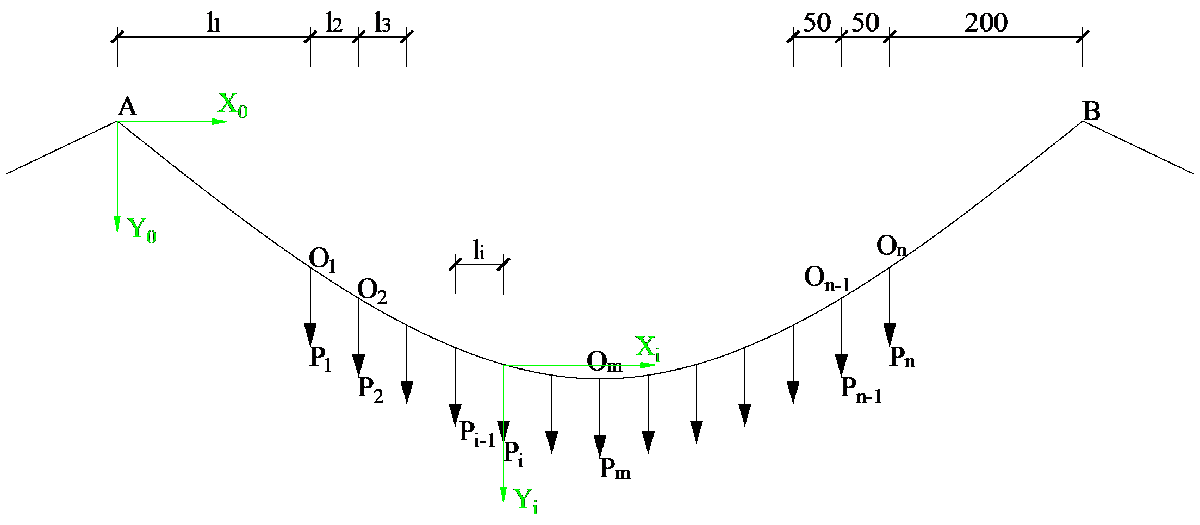

以A点或者$O_i$点为原点，建立局部 $X_i -Y_i$坐标系如图中绿色箭头所示。$\tilde{O_i O_{i+1} }$段主缆的悬链线方程为：


$$y_i =c\left\lbrack \cosh \left(\frac{x_i }{c}+a_i \right)-{\cosh \;a}_i \right\rbrack \;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\left(1\right)$$


根据任一吊点处的竖向力平衡，可以推出$a_{i+1}$和$a_i$的递推公式为：


$$a_{i+1} =\textrm{asinh}\left\lbrack \sinh \left(\frac{l_i }{c}+a_i \right)-\frac{P_i }{H}\right\rbrack \;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\left(2\right)$$


## 循环or递归？

递归的内存占用取决于num_iter也就是吊杆数n+1，当吊杆数增多时，递归的内存占用就会增加，所以不适合使用递归。

使用循环进行迭代时，须得从a1开始计算到ai，嵌套公式从里往外解套

function ai = Iter_ai(num_iter,q,Li,P,x)
    % num_iter = 1:n+1
    % 主缆自重q，单位kN/m
    % Li为每个悬链线分段的水平长度组成的向量，length(Li) == n+1
    % 吊杆拉力P，P中每个元素表示第i根吊杆的拉力P_i，length(P) == n
    % 为方便优化求解，这里将H和a1合并成一个向量x传入即：
    H = x(1);
    a1 = x(2);
    
    c = -H/q;
    
    if num_iter == 1
        ai = a1;
    elseif num_iter > 1
        ai = a1;
        for i = 1:num_iter-1 % 注意迭代区间，从1开始，到num_iter-1结束
            ai = asinh(sinh(Li(i)/c + ai) - P(i)/H); % 公式(2)
        end
    end

    
end